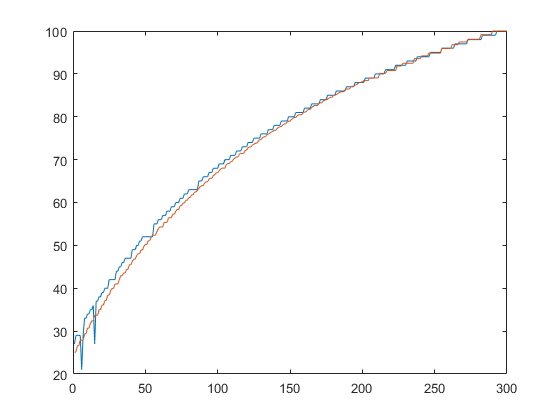

clear all
close
clc
load('3dvar.mat');
[max_res3d, I3d] = max(sres,[], 1);
grid on
plot(I3d)
load('2dvar.mat');
[max_res2d, I2d] = max(ligth_intensity,[], 1);
hold on
plot(I2d./(max(I2d))*(max(I3d)))

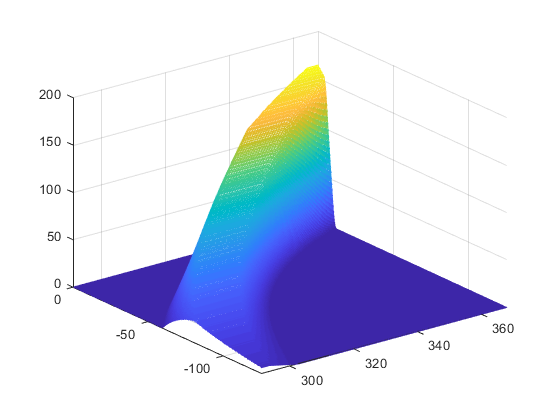

load('2dvar200_400_400.mat');
Sres_sm = zeros(size(ligth_intensity));
for i = 1:size(ligth_intensity,1)
    Sres_sm(i,:) = smooth(ligth_intensity(i,:),50);
end
figure

number_coord_fiber = 400;
fiber_coord = 200:(400-200+1)/number_coord_fiber:400;
ligth_start_coordX = -126 : 0.2540:0;
[X,Y] = meshgrid(fiber_coord, ligth_start_coordX);
mesh(X,Y,Sres_sm)
xlim([291 368])
ylim([-126 0])

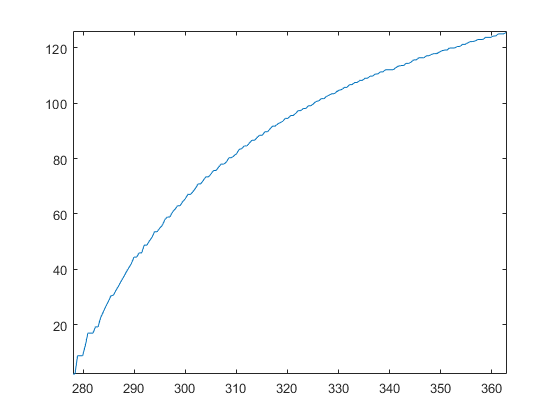


[max_res3ds, I2ds] = max(Sres_sm,[], 1);
figure
grid on
[~, i_first] = min(abs(fiber_coord - 278));
[~, i_last] = min(abs(fiber_coord - 363));
I_f =  I2ds(i_first:i_last)*0.2540;
plot(fiber_coord(i_first:i_last), I_f)
xlim([278 363])
ylim([2.286 126])

I_f = [0 I_f]

I_f =          0    2.2860    2.2860    8.8900    8.8900    8.8900   12.4460   17.0180   17.0180   17.0180   19.3040   19.3040   22.6060   24.6380   26.6700   28.4480   30.4800   30.7340   32.5120   34.0360   35.8140   37.3380   39.1160   40.6400   42.1640   44.4500   44.4500   45.9740   45.9740   48.7680   48.7680   50.2920   51.5620   53.5940   53.5940   54.8640   55.8800   57.9120   58.9280   58.9280   60.7060   61.7220   62.9920   62.9920   64.5160   65.5320   67.0560   67.0560   68.0720   69.3420


coefs = polyfit(fiber_coord(i_first-1:i_last), I_f, 5);

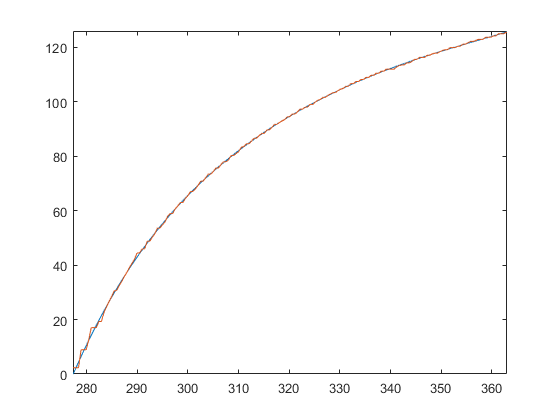

fiber_coord_new = 277:0.01:363;
y1 = polyval(coefs,fiber_coord_new);
figure
grid on
plot(fiber_coord_new,y1)
hold on 
plot(fiber_coord, I2ds*0.2540)
xlim([277.3 363])
ylim([0 126])

y_cord = 0:126/19:126;
fiber_cord = zeros(size(y_cord));
y2 = y1(y1>=0)

y2 =     0.0042    0.0471    0.0899    0.1328    0.1756    0.2183    0.2611    0.3039    0.3466    0.3893    0.4320    0.4747    0.5174    0.5600    0.6027    0.6453    0.6879    0.7305    0.7731    0.8156    0.8582    0.9007    0.9432    0.9857    1.0282    1.0706    1.1131    1.1555    1.1979    1.2403    1.2827    1.3250    1.3674    1.4097    1.4520    1.4943    1.5366    1.5788    1.6211    1.6633    1.7055    1.7477    1.7899    1.8321    1.8742    1.9163    1.9585    2.0006    2.0426    2.0847


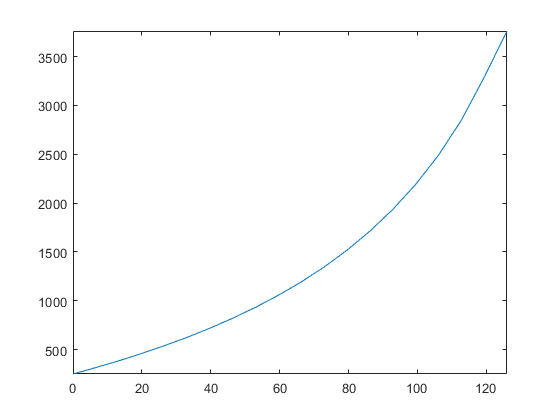

for i = 1:length(y_cord)
    [~, fiber_cord(i)] = min(abs(y2 - y_cord(i)));
end
Result_for_motor = (round(250 + fiber_cord/length(y2).*3513))';
figure
% Result_for_motor = Result_for_motor((1:50));
plot(y_cord,Result_for_motor)
xlim([0 max(y_cord)])
ylim([250 3763])

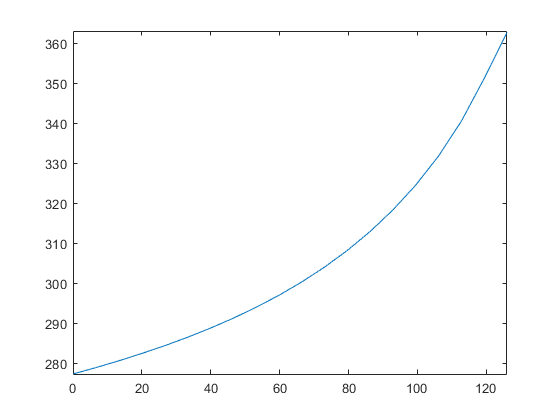

Result_for_matlab = fiber_cord/length(fiber_coord_new).*(363-277.3)+277.3;
figure
% Result_for_matlab = Result_for_matlab(1:100);
plot(y_cord,Result_for_matlab)
xlim([0 max(y_cord)])
ylim([277.3 363])

% coefinv = polyfit(I_f, fiber_coord(i_first:i_last), 5);
% Result_for_matlabinv = 278:((363-278+1)/10):363;
% y1 = polyval(coefs,Result_for_matlabinv);
% figure
% hold on
% grid on
% plot(I_f,fiber_coord(i_first:i_last))
% plot(y1,Result_for_matlabinv,'*')
% ligth_start_coordX = y1;
